Nn = 1000;

uk = rand(Nn+1,1)/2;

% figure; hold on;
% plot(0:Nn,uk,'LineWidth',2);
% xlabel('samples')

yk = zeros(Nn+1,1);
for i = 3:Nn+1
    yk(i) = 0.4*yk(i-1)+0.4*yk(i-1)*yk(i-2)+0.6*(uk(i-1))^3+0.1;
end

% figure; hold on;
% plot(0:Nn,yk,'LineWidth',2);
% xlabel('samples')
% xlim([2 Nn])

dt = 0.1; %ms
D = 1/dt;
J = 1;
pw = 25;  %ms
res_t = 10;  %ms
detector_int = 0.1;  %ms
pmax = 0.1;%mW
poffset = 0.0; %mW

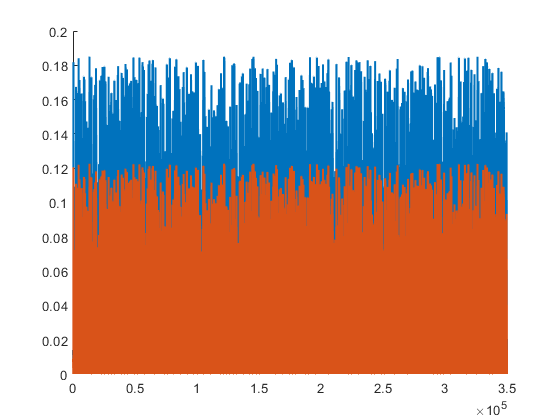

segm = round(ceil(Nn/J));

% inp = zeros(N,J*segm);
% inp(1:N,1:idx) = inp_train;

L = round(segm*(pw+res_t)*D);

K = 4;
C = 4;
%K = 2;


inp_w = rand(K,1);
% inp_w = zeros(K,1);
% inp_w(1) = 1;

inp = uk*inp_w';
inp = (inp-min(inp,[],'all'))/max(inp,[],'all');

inpm = zeros(K,L);

for k = 1:K
    for i = 1:segm
        for j = 1:J
            inpm(k,round((i-1)*(pw+res_t)*D+(j-1)*(pw*D/J))+1:round((i-1)*(pw+res_t)*D+j*pw*D/J)) = sqrt(pmax*inp((i-1)*J+j,k)+poffset);
        end
    end
end

figure; hold on;
plot(inpm(1,:),'LineWidth',1.5);
plot(inpm(2,:),'LineWidth',1.5);

% inpm = zeros(N, L);
% for j = 1:N
%     for i = 1:segm
%         for k = 1:J
%             inpm(j,round((i-1)*(pw+res_t)*D+(k-1)*(pw*D/J))+1:round((i-1)*(pw+res_t)*D+k*pw*D/J)) = sqrt(pmax*inp(j,(i-1)*J+k)+poffset);
%         end
%     end
% end

% temp = zeros(2,1);
% out_M = zeros(L,2);
% hvec = 0.8;
% hmatrix = zeros(1,L);
% Pmatrix = zeros(1,L);
% omvec = zeros(2,L);
% theta = zeros(1,2);
% theta(1) = 0.6155;
% %theta(1) = pi/4;
% theta(2) = pi/3;
% 
% for i = 1:L
%     [temp(1), temp(2),hnvec,P,o1,o2] = RC_1coup(inpm(1,i),inpm(2,i),theta,hvec,dt);
%     out_M(i,1:2) = (abs(temp(1:2))).^2;
%     hvec = hnvec;
%     hmatrix(i) = hvec;
%     Pmatrix(i) = P;
%     omvec(1,i) = abs(o1)^2;
%     omvec(2,i) = abs(o2)^2;
%     %disp(i);
% end



out_M = zeros(L,K);
hvec = 0.8*ones((K-1)*C/2+mod(C,2)/2);
hmatrix = zeros(L,(K-1)*C/2+mod(C,2)/2);
Pmatrix = zeros(L,(K-1)*C/2+mod(C,2)/2);
theta = pi/3*ones((K-1)*C/2+mod(C,2)/2,1);
flag = zeros(K*(K-1)/2,1);
for i = 1:L
    inp_ = inpm(:,i);
    [temp, hnvec,P] = RC_KxC(inp_,theta,hvec,dt,K,C,flag);
    out_M(i,1:K) = (abs(temp(1:K))).^2;
    hvec = hnvec;
    hmatrix(i,:) = hvec(:);
    Pmatrix(i,:) = P(:);
    %disp(i);
end

% out1 = zeros(1001,1);
% out2 = zeros(1001,1);
% phi_vec = -pi:2*pi/1000:pi;
% for i = 1:1001
%     [out1(i), out2(i)] = node_coup(exp(1i*phi_vec(i)),1,pi/4);
% end
% figure; hold on;
% plot(phi_vec,abs(out1));
% plot(phi_vec,abs(out2));


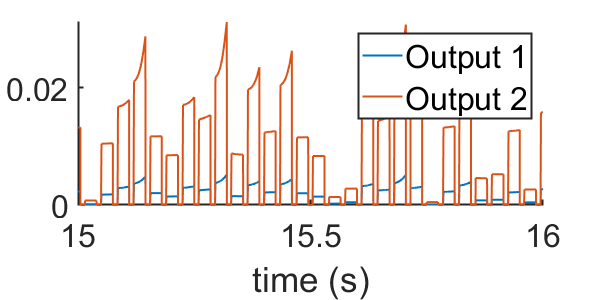

time_vec = (dt:dt:dt*L)/1e3;
figure; hold on;
plot(time_vec,out_M(:,1),'LineWidth',1.5);
plot(time_vec,out_M(:,2),'LineWidth',1.5);
xlim([15 16])
xlabel('time (s)')

set(gca,'FontSize',24)
set(gca,'linewidth',1.5)
%title('SD OCT')
set(gcf,'Position',[0 0 600 300])

lgd = legend('Output 1','Output 2');
lgd.FontSize = 24;

% time_vec = (dt:dt:dt*L)/1e3;
% figure; hold on;
% plot(time_vec,omvec(1,:),'LineWidth',1.5);
% plot(time_vec,omvec(2,:),'LineWidth',1.5);
% xlim([15 16])
% xlabel('time (s)')
% 
% set(gca,'FontSize',24)
% set(gca,'linewidth',1.5)
% %title('SD OCT')
% set(gcf,'Position',[0 0 600 300])
% 
% lgd = legend('Output 1','Output 2');
% lgd.FontSize = 24;


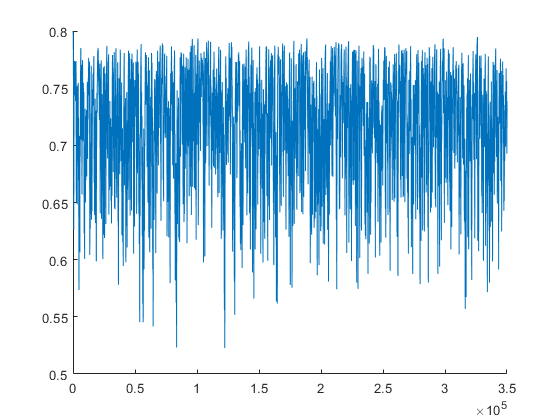

figure; hold on;
plot(hmatrix(:,3));

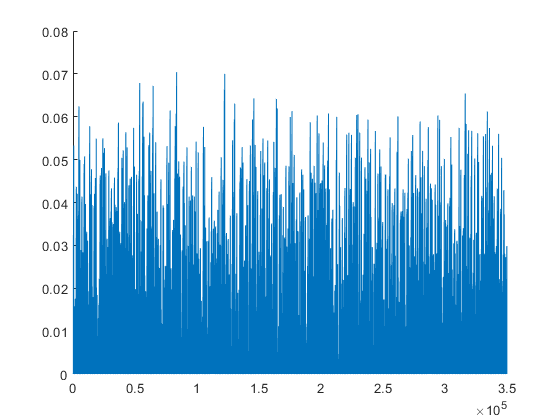

figure; hold on;
plot(Pmatrix(:,3));

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%% Training %%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Ntrain = 400;
train_start = 20;
out_train = out_M(train_start*(pw+res_t)*D+1:(train_start+Ntrain)*(pw+res_t)*D,:);
input_train = zeros(Ntrain,K*pw*D/J);

segm = round(ceil(Ntrain/J));
for i = 1:segm
    for j = 1:J
        for k = 1:K
            input_train((i-1)*J+j,(k-1)*pw*D/J+1:k*pw*D/J) = out_train(round((i-1)*(pw+res_t)*D+(j-1)*(pw*D/J))+1:round((i-1)*(pw+res_t)*D+j*pw*D/J),k);
        end
    end
end

ytrain = yk(train_start+2:train_start+Ntrain+1);

kc = 0.000001;

w = ridge(ytrain,input_train,kc,0);

yo = w(1) + input_train*w(2:end);

err = immse(ytrain,yo)/immse(ytrain,zeros(Ntrain,1))

err = 0.0011

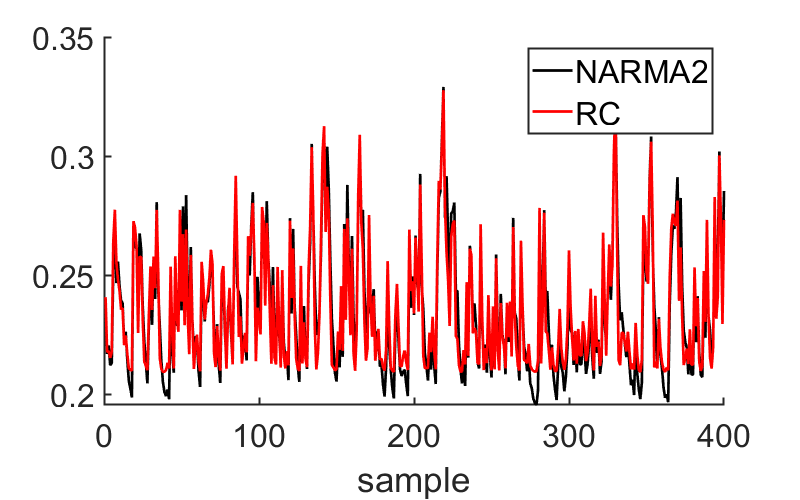

figure; hold on;
plot(ytrain,'linewidth',2,'Color','k');
plot(yo,'linewidth',2,'Color','r');
xlabel('sample')

set(gca,'FontSize',24)
set(gca,'linewidth',1.5)
%title('SD OCT')
set(gcf,'Position',[0 0 800 500])

lgd = legend('NARMA2','RC');
lgd.FontSize = 24;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%% Testing %%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Ntest = 100;
test_start = 700;
out_test = out_M(test_start*(pw+res_t)*D+1:(test_start+Ntest)*(pw+res_t)*D,:);
input_test = zeros(Ntest,2*pw*D/J);

segm = round(ceil(Ntest/J));
for i = 1:segm
    for j = 1:J
        for k = 1:K
            input_test((i-1)*J+j,(k-1)*pw*D/J+1:k*pw*D/J) = out_test(round((i-1)*(pw+res_t)*D+(j-1)*(pw*D/J))+1:round((i-1)*(pw+res_t)*D+j*pw*D/J),k);
        end
    end
end

ytest = yk(test_start+2:test_start+Ntest+1);

yo = w(1) + input_test*w(2:end);

err = immse(ytest,yo)/immse(ytest,zeros(Ntest,1))

err = 8.0659e-04

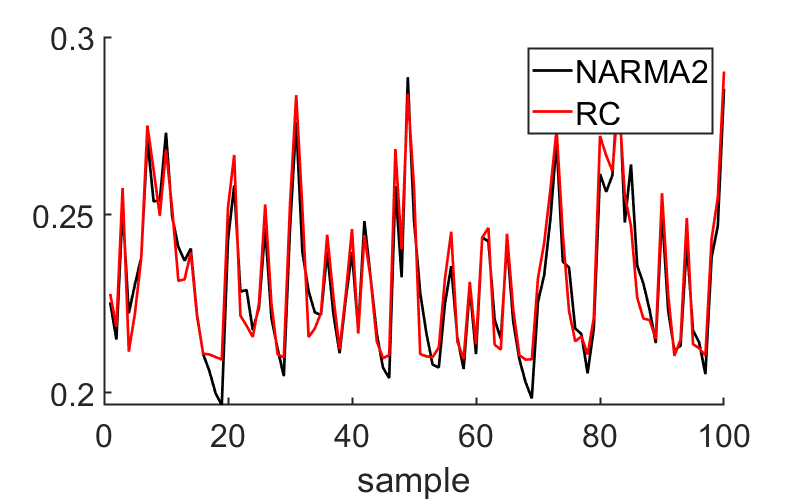


figure; hold on;
plot(ytest,'linewidth',2,'Color','k');
plot(yo,'linewidth',2,'Color','r');
xlabel('sample')

set(gca,'FontSize',24)
set(gca,'linewidth',1.5)
%title('SD OCT')
set(gcf,'Position',[0 0 800 500])

lgd = legend('NARMA2','RC');
lgd.FontSize = 24;